load('Tire model/TTC data files/B1965run2.mat')

Inflation pressure of 12 psi goes from 1-19984

12 psi, 0 camber is 1-7495

1-1249

1250-2498

2499-3746

3747-4996

4997-6245

6246-7495

Group data:

length=size(ET);
scalefactor=0.6;
[loadlb,loadub]=groupdata(FZ(1:7495),6,100,0);

Fit Pacejka function to data:

%for i=1:size(loadlb,1)
%    start = 0;
%    if (i>1)
%        start=loadub(i-1);
%    end
%    [SAlb,SAub]=groupdata(SA(loadlb(i):loadub(i)),3,0.19,start);
%    fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA
%    fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));
%end

C=zeros(12,3);
[SAlb,SAub]=groupdata(SA(loadlb(1):loadub(1)),3,0.19,0);
C(1,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


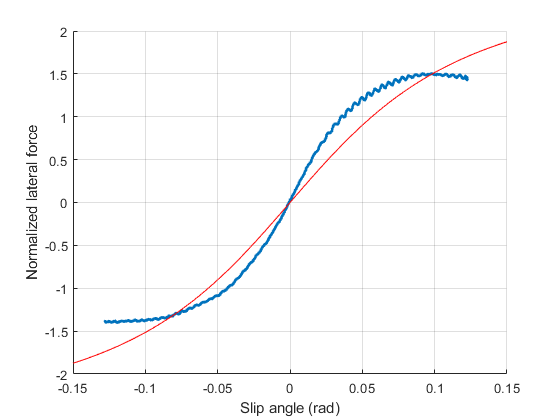


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(2,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

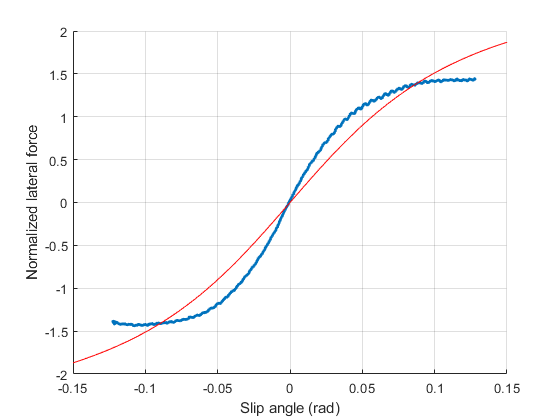


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(2):loadub(2)),3,0.19,loadub(1));
C(3,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

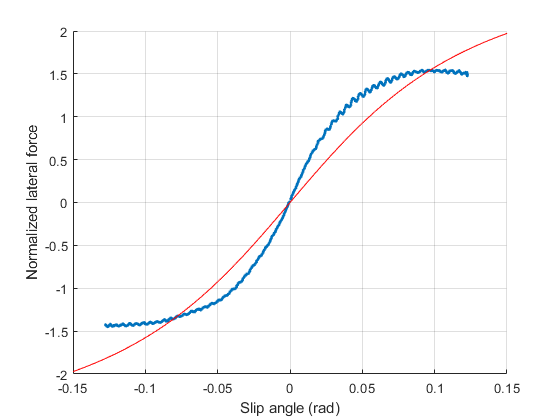


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(4,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

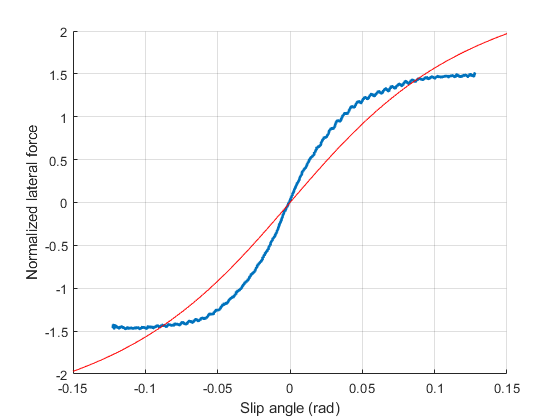


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(3):loadub(3)),3,0.19,loadub(2));
C(5,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

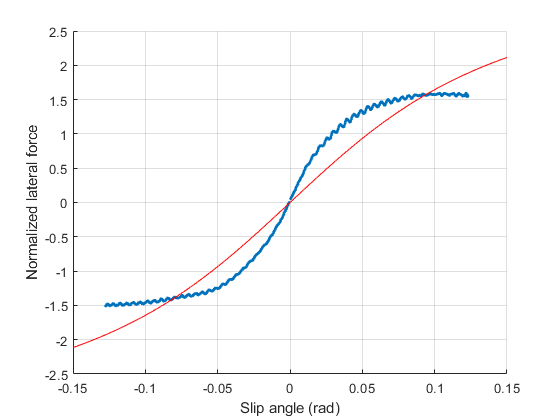


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(6,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

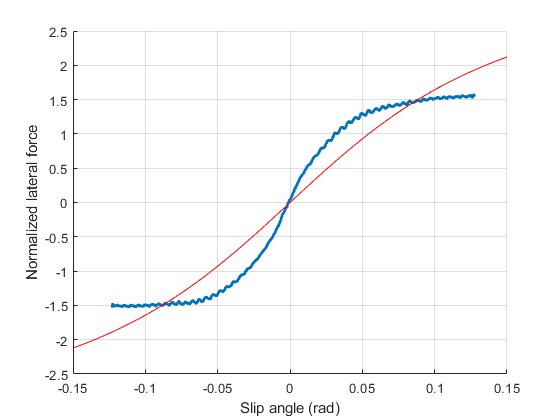


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(4):loadub(4)),3,0.19,loadub(3));
C(7,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

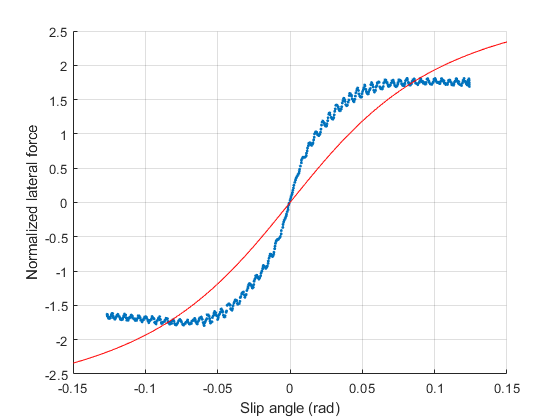


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(8,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

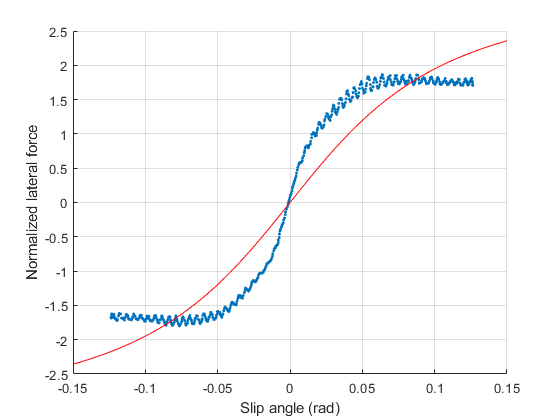


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(5):loadub(5)),3,0.19,loadub(4));
C(9,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

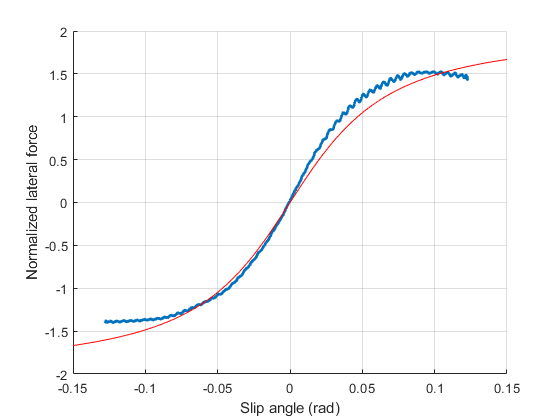


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(10,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

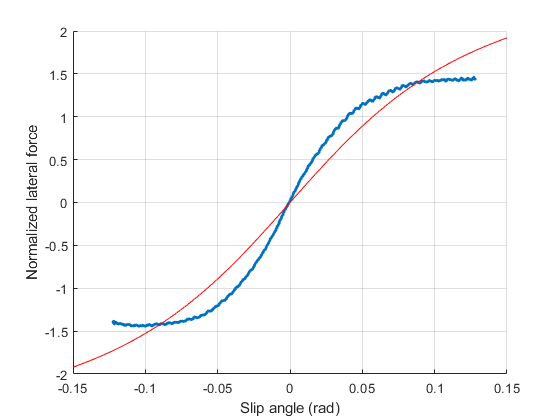


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(6):loadub(6)),3,0.19,loadub(5));
C(11,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

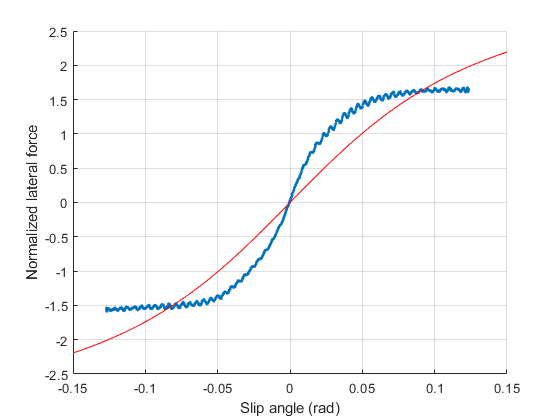


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


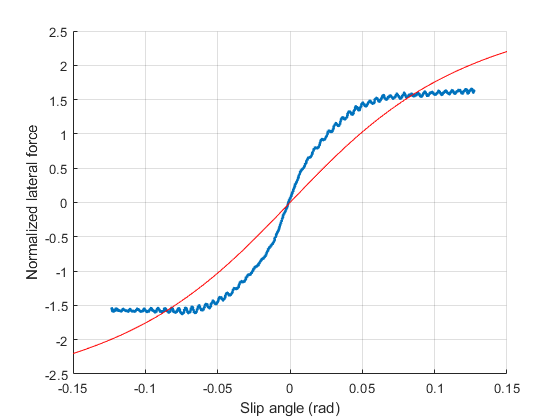

C(12,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


save('Tire model/pacejka_coefficients_lateral.mat',"C");
% stiff=zeros(12,1);
% for j=1:12
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('lateral_stiffness.mat',"stiff");

Define Pacejka function:

function y = pacejka(C,sigma)
    y=C(3)*sin(C(2)*atan(atan(C(1)*sigma)));
end

Fit curve for a single vertical load group:

function C = fit(alpha_unscaled,mu_unscaled)
hold off
scalefactor=0.6;
alpha=alpha_unscaled*scalefactor;
alpha=deg2rad(alpha);
sigma_y=tan(alpha);
mu=mu_unscaled*scalefactor;
scatter(alpha,mu,5,'filled')
hold on
lb=-inf*ones(3,1);
ub=inf*ones(3,1);
C0=[1,1,1];
options=optimoptions('lsqcurvefit','MaxFunctionEvaluations',1000);
[Cfinal,~,~,~,~] = lsqcurvefit(@pacejka,C0,sigma_y,mu,lb,ub,options);
x=linspace(-0.15,0.15,100);
plot(x,pacejka(Cfinal,tan(x)),'red')
xlabel('Slip angle (rad)')
ylabel('Normalized lateral force')
grid on
hold off
C=Cfinal;
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
    lb=zeros(n,1);
    ub=zeros(n,1);
    lb(1)=1;
    x = 0;
    for i=1:n
        if i>1
            lb(i)=ub(i-1)+1;
        end
        while 1
            x=x+1;
            if (x == size(data,1)) || (abs(data(x) - data(x+1)) > range)
                ub(i)=x;
                break
            end
        end
    end
    lb=lb+start*ones(n,1);
    ub=ub+start*ones(n,1);
end